# This is the live script for ESE 6190 HW7 Explicit, Robust, & Hybrid MPC Exercise 2

clear all
clc

## 2.1-2.3 Nominal Explicit MPC with LQR terminal cost and constraints

## 2.1 design MPC

% system dynamics
A = [1.2 1; 0 1];
B = [0; 1];
% state constraints
xmin = [-15; -15];
xmax = [15; 15];
% input constraints
umin = -1;
umax = 1;
% MPC stage costs
Q = eye(2);
R = 1;
% MPC terminal constriants and cost, use LQR
[P,~,K] = dare(A,B,Q,R);
Finf = -K;
Acl = A + B*Finf;
system_Terminal = LTISystem('A',Acl);
Xtilde = Polyhedron('A',[eye(2);-eye(2);Finf;-Finf],'b',[15;15;15;15;1;1]);
Oinf = system_Terminal.invariantSet('X',Xtilde);

Iteration 1...
Iteration 2...


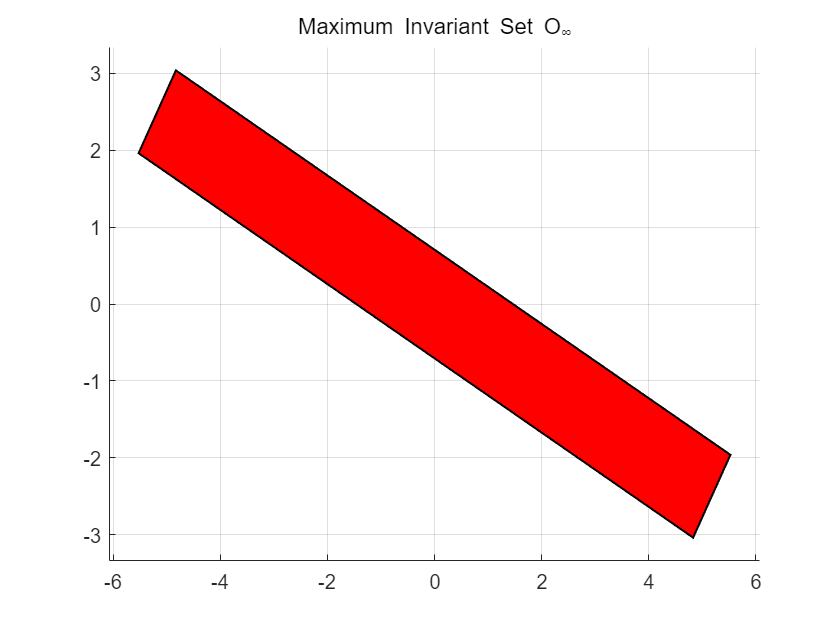

figure
plot(Oinf)
title('Maximum Invariant Set O_∞')

Af = Oinf.A;
bf = Oinf.b;
% MPC horizon
N = 3;

## 2.2 Explicit MPC solution

x = sdpvar(2,1);
U_sol = mympc_explicit(A,B,Q,R,P,N,umin,umax,xmin,xmax,Af,bf,x);
U = U_sol.xopt
u = U.feval([2;-1], 'primal');
figure;
hold on
title('Piecewise Affine Controller u*(x_0)')
xlabel('x_{01}')
ylabel('x_{02}')
U.fplot('primal');
view([-160 30]);

## 2.3 Simulate 25 closed-loop state trajectory

% pre calculate the explicit solution offline
x = sdpvar(2,1);
U_sol = mympc_explicit(A,B,Q,R,P,N,umin,umax,xmin,xmax,Af,bf,x);
U = U_sol.xopt;
T_sim = 25;
% initial condition
x0 = [2;-1];

% record for the plot
n = size(A, 1);
m = size(B, 2);
U_record = zeros(T_sim*m,1);
X_record = zeros(T_sim*n,1);

% do the simulation with explicit lookup online
for i = 1 : T_sim
    if i == 1
        x = x0;
    end
    u = U.feval(x, 'primal');
    u = u(1);
    xp = system_sim(x,u,A,B);
    U_record((i-1)*m+1:i*m,1) = u;
    X_record((i-1)*n+1:i*n,1) = xp;
    x = xp;
end
X_record = [x0;X_record];
figure;
hold on
grid on
plot(X_record(1:n:end),X_record(2:n:end),'-o','LineWidth',2,'Color','b','MarkerFaceColor','b','MarkerSize',4)
title('x_0 = [2;-1], Q=I, R=1, N=3, P_N=P_R, x_N=O_∞, closed loop trajectory')
ylabel('x_2')
xlabel('x_1')

## MPC controller function and simulating helper function

function U_sol = mympc_explicit(A,B,Q,R,P,N,umin,umax,xmin,xmax,Af,bf,x)
%% This is the function used to solve the linear mpc problem
    %% linear quadratic optimal control via recursive approach
    %% The method is batch-approach based with substitution, i.e. shooting
    %% essentially, it is solving multiparametric QP about initial state x
    %% input:
    %  A: system matrix; B: Input matrix; N: control horizon;
    %  Q,R: weight matrices for states and inputs, respectively;
    %  P: terminal cost weight matrix;
    %  umin,umax: box constraints for control inputs, vectors
    %  xmin,xmax: box constraints for state inputs, vectors
    %  Af, bf: Terminal state constraint (convex polytope region)
    %  x: the current state (or say, the initial state for every mpc
    %  planning), should be a sdp variable to do the mp-QP
    %% output:
    %  u: the mpc control sequence u = [u0; u1; ...; uN-1];

    % first, rollout the dynamics to get Sx(mathcalA) and Su(mathcalB):
    n = size(A, 1);
    m = size(B, 2);
    Sx = zeros((N+1)*n, n);
    Su = zeros((N+1)*n, N*m);
    for i = 0:N
        Sx(i*n+1:(i+1)*n, 1:n) = A^i;
        for j = 0:N-1
            Su(i*n+1:(i+1)*n, j*m+1:(j+1)*m) = (i-j-1>=0)*A^(i-j-1)*B;
        end
    end

    % Then, get the stack-up weight matrices and rearrage as quadratic form
    % Q_bar(mathcal Q) and R_bar(mathcal R)
    I_N = eye(N);
    Q_bar = kron(I_N, Q);
    Q_bar(end+1:end+n, end+1:end+n) = P;
    R_bar = kron(I_N, R);
    H = 2*(Su'*Q_bar*Su + R_bar);
    F = 2*Sx'*Q_bar*Su;
    Y = x'*Sx'*Q_bar*Sx*x;
    
    % add state and input constraints, write them in inequality form
    % here write input constraints also in the stack-up inequality
    % infact, can use quadprog's lb and ub to set the input constraints 
    % since decision variable is u
    % x in (xmin, xmax), u in (umin, umax), xf in (xmin, xmax)
    Ax = [eye(n); -eye(n)];
    Au = [eye(m); -eye(m)];

    % constrauct G block by block
    G_u_block = kron(I_N,Au);
    % here 2 because we have 2 states and need to set upper and lower limit for each state
    % for more general case, consider using num_con_x = size(Ax,1)/n
    % i.e. num_con_x = 2 here
    G_x_block = zeros(N*n*2, N*m);
    for i = 0:N-1
        for j = 0:N-1
            G_x_block(i*2*n+1:(i+1)*2*n, j*m+1:(j+1)*m) = (i-j-1>=0)*Ax*A^(i-j-1)*B;
        end
    end

    % num_terminal_constraint = size(Af,1)/n
    num_tc = size(Af,1)/n;
    G_xf_block = zeros(n*num_tc, N*m);
    for j = 0:N-1
        G_xf_block(:, j*m+1:(j+1)*m) = (N-j-1>=0)*Af*A^(N-j-1)*B;
    end
    G = [G_u_block; G_x_block; G_xf_block];

    % construct E block by block
    E_u_block = zeros(N*2, n);
    E_x_block = zeros(N*n*2, n);
    for i = 0:N-1
        E_x_block(i*n*2+1:(i+1)*n*2, 1:n) = -Ax*A^i;
    end
    E_xf_block = -Af*A^N;
    E = [E_u_block;E_x_block;E_xf_block];

    % construct w block by block
    bu = [umax;-umin];
    bx = [xmax;-xmin];
    w_u_block = kron(ones(N,1),bu);
    w_x_block = kron(ones(N,1),bx);
    w = [w_u_block;w_x_block;bf];

    % Get the MPC control input from solving the mp-QP
    U = sdpvar(m*N,1);
    J = U'*H*U + 2*x'*F*U;
    C = [G*U <= w+E*x];
    mpQP = Opt(C, J, x, U);
    U_sol = mpQP.solve();
end

function xp = system_sim(xk, uk, A, B)
    %% This is the function used to simulate single-step dynamics of the system
    %% input:
    %  A: system matrix; B: Input matrix; D: Disturbance matrix;
    %  xk: current state, uk: current input
    xp = A*xk + B*uk;
end